# **A lowpass digital filter’s specifications are given by:**

# **𝜔𝑠 = 0.65𝜋 𝑟𝑎𝑑𝑖𝑎𝑛𝑠, 𝜔𝑝 = 0.45 𝑟𝑎𝑑𝑖𝑎𝑛𝑠, 𝐴𝑠 = 60 𝑑𝐵, 𝐴𝑝 = 0.25 𝑑𝐵**

% Digital Filter Specifications:
wp = 0.45; % digital Passband Normalized freq 
ws = 0.65; % digital Stopband Normalized freq 
Ap = 0.25; % Passband ripple in dB
As = 60; % Stopband attenuation in dB

**a. Using bilinear transformation and the Chebyshev I approximation approach obtain a system function H(z) in the cascade form that satisfies the above specifications.**

[N,omegac] = cheb1ord(wp,ws,Ap,As)

N = 8

omegac = 0.4500

[C,D] = cheby1(N,Ap,omegac)

C =     0.0011    0.0086    0.0300    0.0601    0.0751    0.0601    0.0300    0.0086    0.0011


D =     1.0000   -2.8299    5.3214   -6.7905    6.4563   -4.5523    2.3297   -0.7968    0.1448


[B,A] = bilinear(C,D,1)

B =     0.0767   -0.2045    0.2385   -0.1590    0.0663   -0.0177    0.0029   -0.0003    0.0000


A =     1.0000   -9.2191   38.9157  -98.4707  163.9609 -184.8270  138.8337  -64.2442   14.4545


**b. Provide design plots in the form of log-magnitude, phase, group-delay, and impulse responses.**

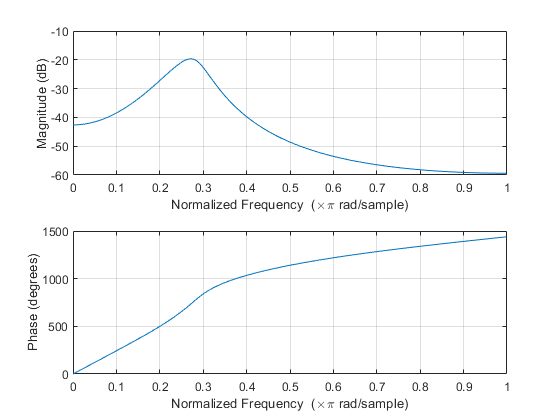

freqz(B,A)

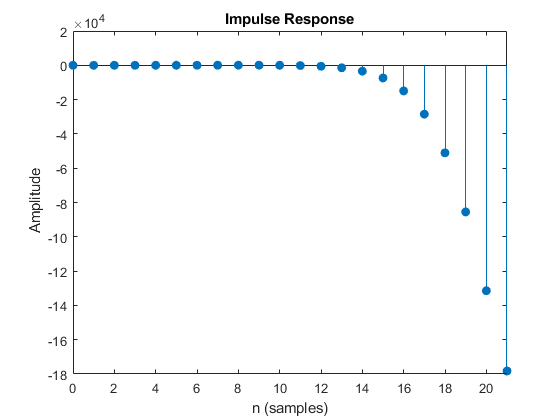

impz(B,A)

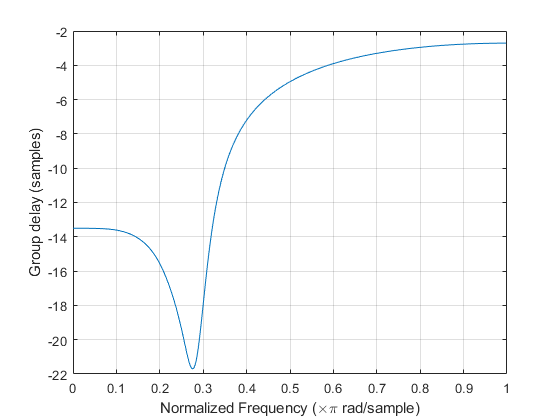

grpdelay(B,A)

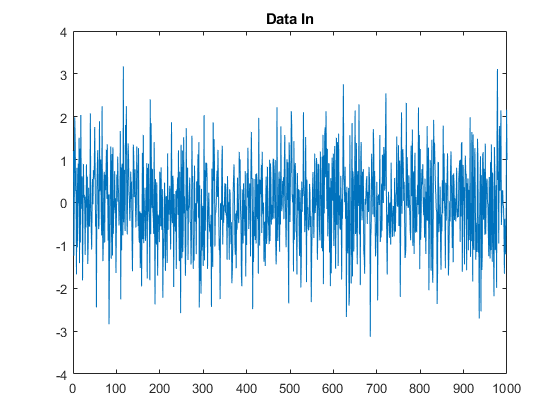

dataIn = randn(1000,1);
dataOut = filter(B,A,dataIn);
plot(dataIn)
title('Data In')

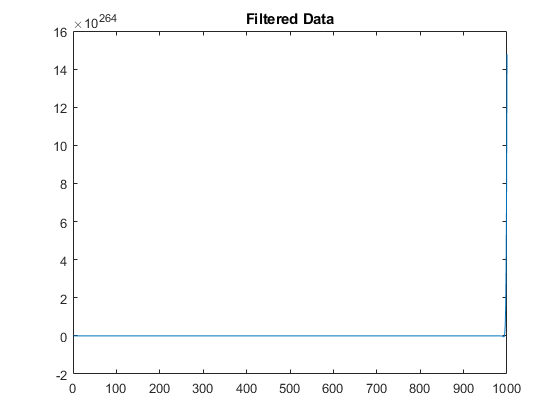

plot(dataOut)
title("Filtered Data")  

**c. Determine the exact band-edge frequencies for the given attenuation.**

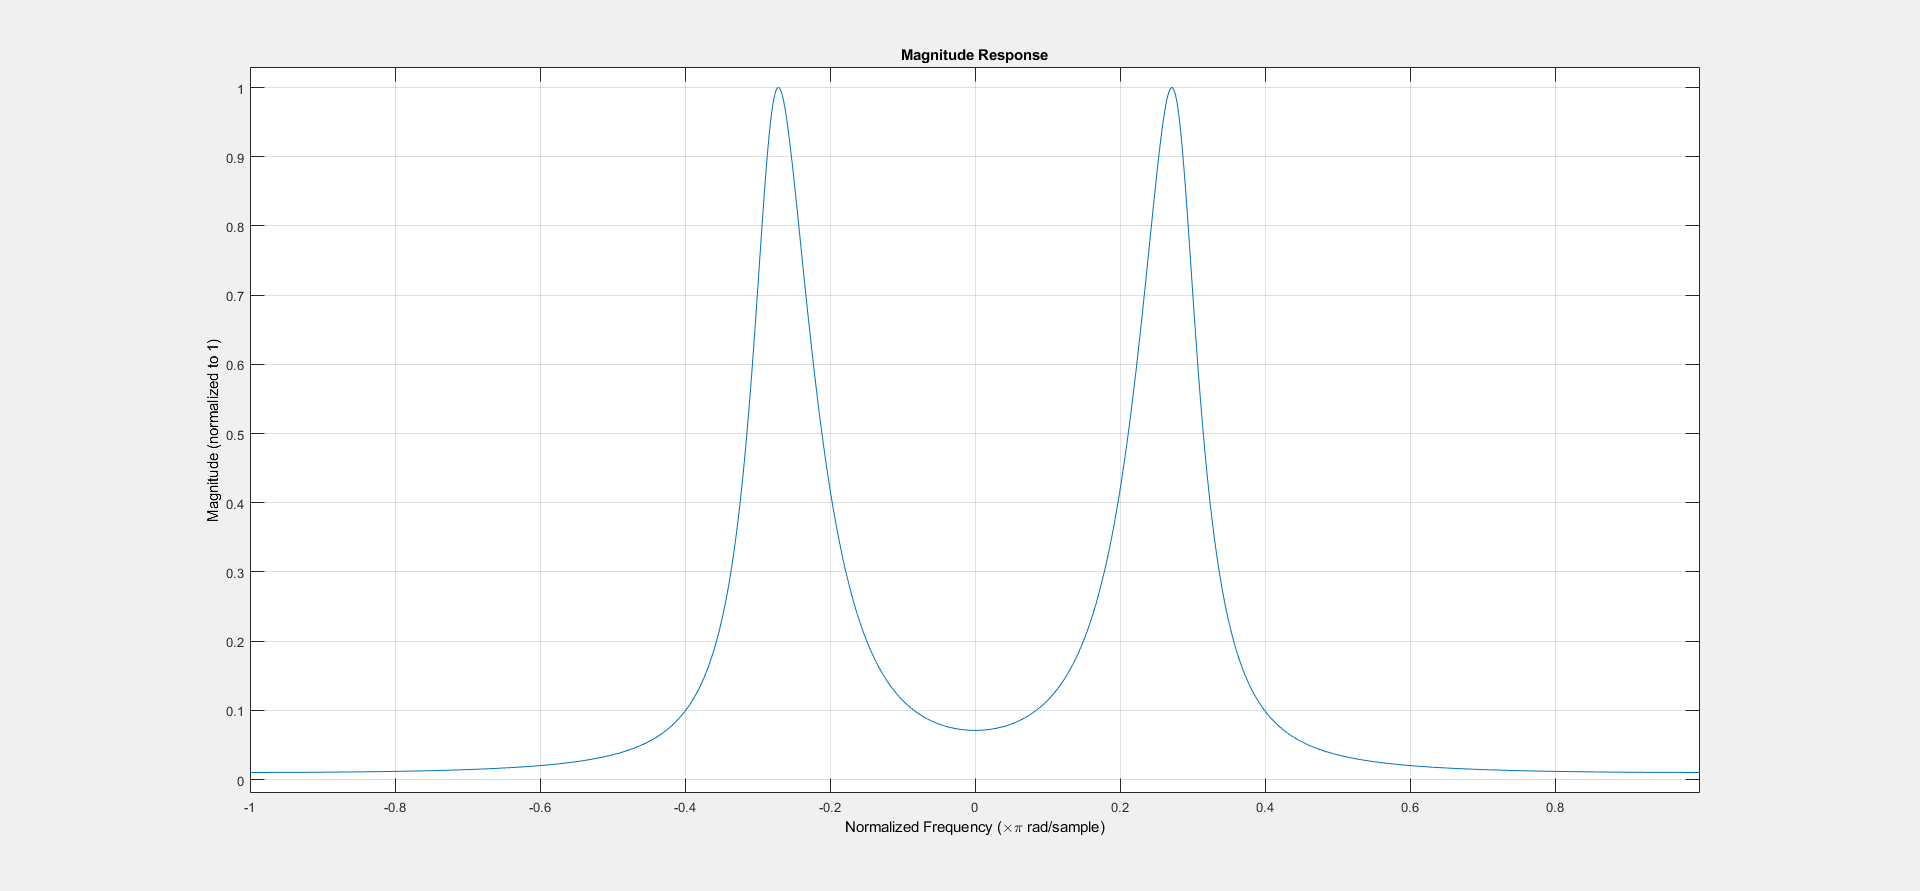

fvtool(B,A,'magnitude')

load('q8_3_c.mat')
cursor_info2

cursor_info2 = 1×2 struct array with fields:
    Target
    Position
    DataIndex


**From Graph we can see the band edges are at 0.3pi and 0.23pi**